依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

热图B: leant light-water；transfer aud-water； final aud-water，只取命中小于0.8的

DataSet=TransferLearning.FullCalcium;

%鼠内每个回合的细胞数都一样，因此没必要排除因细胞而重复的回合
TransferPerfomance=groupsummary(DataSet.TableQuery(["Mouse","Behavior"],Phase="Transfer",Stimulus="AudioWater",Paradigm="光声",ZLayer=["MOp2/3","MOp5"]),'Mouse','mean');
Mice=TransferPerfomance.Mouse(TransferPerfomance.mean_Behavior<0.8);

排序热图2

QueryTable=UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'Fig2B');
QueryTable.Mouse(:)={Mice};
LAFinal=DataSet.QueryNTATS(QueryTable,UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median);

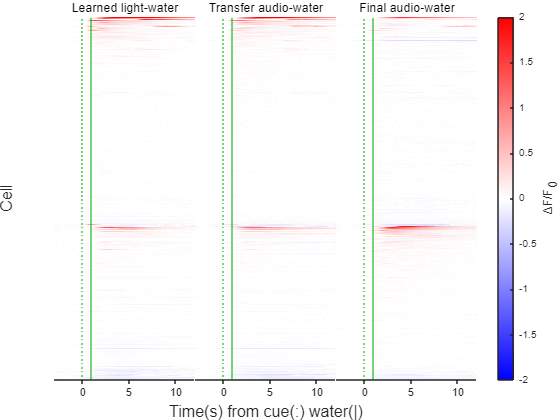

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Data=UniExp.HeatmapSort(LAFinal,["Transfer_audio_water","Final_audio_water"],'descend').NTATS{:,:,["Learned_light_water","Transfer_audio_water","Final_audio_water"]};
Layout=TransferLearning.BasicHeatmap(Data,["Learned light-water","Transfer audio-water","Final audio-water"],Colors,false,CLim=[-2,2]);

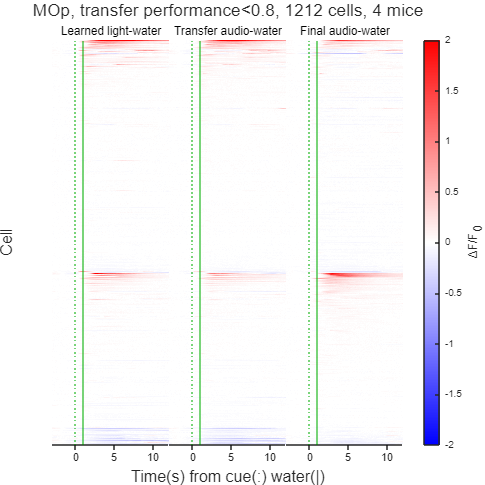

title(Layout,sprintf('MOp, transfer performance<0.8, %u cells, %u mice',height(Data),numel(Mice)));
MATLAB.Graphics.FigureAspectRatio(1,1,1);
print(TransferLearning.ProjectPath('TransferLowPerformanceHeatmap.svg'),'-dsvg');